Fs = 250;
Fpass  = 35;
Fstop = 45;
Dpass = 0.05;
Dstop = 0.0001;

f = [0 Fpass/Fs Fpass/Fs 1];
mhi = [1 1 0 0];
firPB20=fir1(60,Fstop/Fs,'low')

firPB20 =    -0.0008   -0.0006   -0.0001    0.0005    0.0012    0.0018    0.0019    0.0012   -0.0004   -0.0026   -0.0047   -0.0057   -0.0048   -0.0016    0.0036    0.0093    0.0133    0.0136    0.0087   -0.0013   -0.0144   -0.0266   -0.0331   -0.0292   -0.0120    0.0185    0.0589    0.1029    0.1426    0.1701    0.1800    0.1701    0.1426    0.1029    0.0589    0.0185   -0.0120   -0.0292   -0.0331   -0.0266   -0.0144   -0.0013    0.0087    0.0136    0.0133    0.0093    0.0036   -0.0016   -0.0048   -0.0057


bhi34 = fir2(34,f,mhi);
bhi15 = fir2(15,f,mhi);
bhi60 = fir2(60,f,mhi);
bhi100 = fir2(100,f,mhi);
bhi200 = fir2(200,f,mhi);

freqz(bhi34,1,[],Fs)
hold

Current plot held


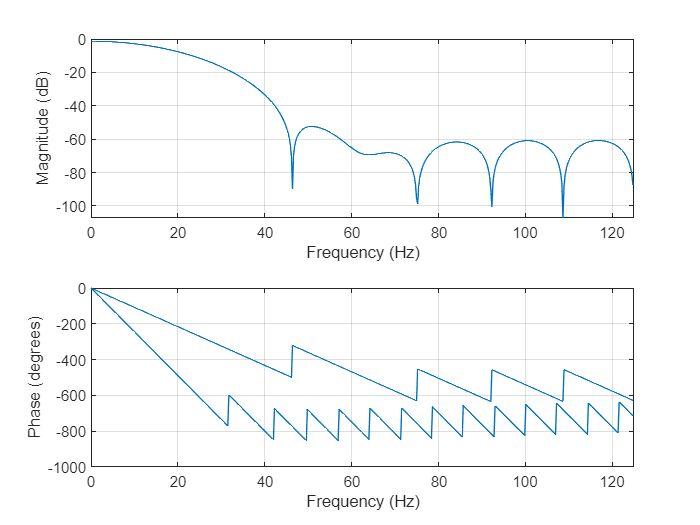

freqz(bhi15,1,[],Fs)

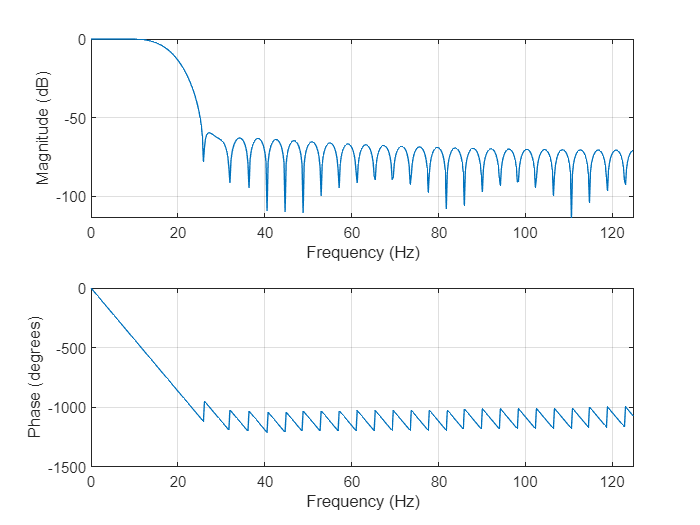

freqz(bhi60,1,[],Fs)

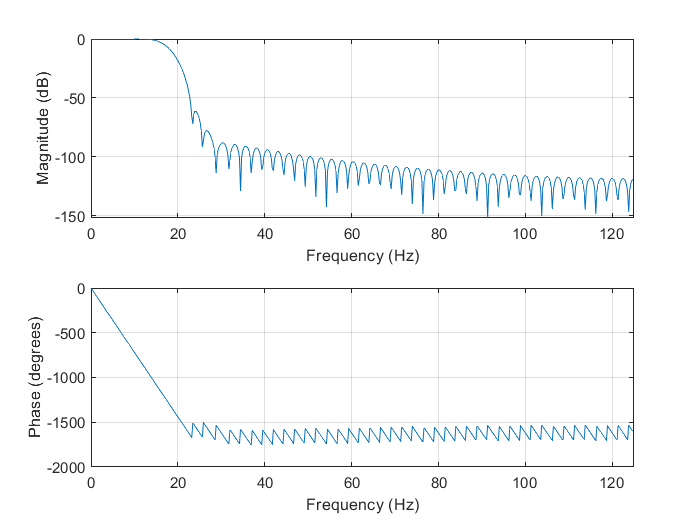

freqz(bhi100,1,[],Fs)

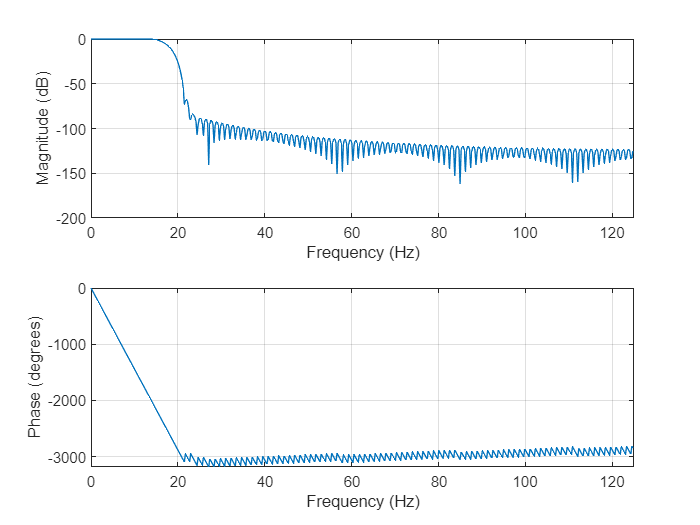

freqz(bhi200,1,[],Fs)

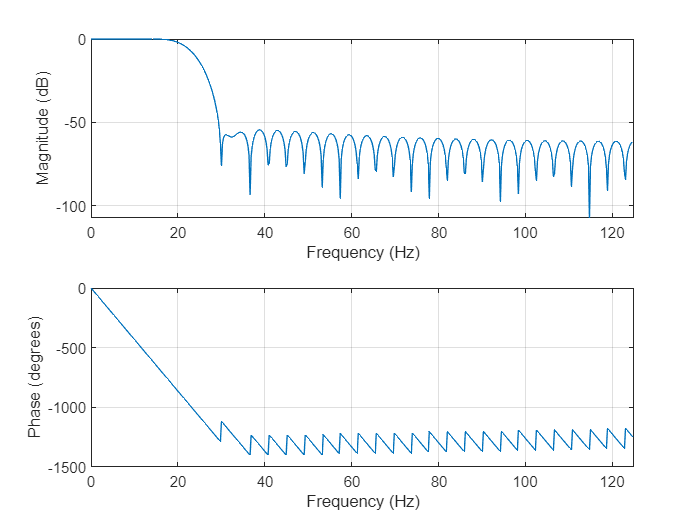

freqz(firPB20,1,[],Fs)

load('HdFIR.mat')

Error using load
'HdFIR.mat' is not found in the current folder or on the MATLAB path, but exists in:
    D:\Desktop\S y A\NeurUN

Change the MATLAB current folder or add its folder to the MATLAB path.

x2 = table2array(readtable('datalog2.csv'));
x1 = table2array(readtable('datalog.csv'));
NumFIR3=[.1 .1 .1 .1 .1 .1 .1 .1 .1 .1];
y2 = filter(NumFIR3,1,x2);
L2 = size(x2,1);  
t2=linspace(0,L2/100,L2);
x2Timeseries= timeseries(x2,t2);
save('SignalX2.mat','x2Timeseries','-v7.3')
%%%------------ Derivates

dx =[0; diff(x2)];
dx2 =[0; diff(dx)];

freqz(Hd12_14)
freqz(NumFIR3,1)

figure(1)
plot(t2,x2,'.-',t2,y2,'.-', t2,dx,t2,dx2)
xlim([0 5])
xlabel('Time (s)')
ylabel('Amplitude')
grid on
legend('Original Signal','Filtered Data','First Deriv','Sec Deriv')
L1 = size(x1,1);  
t1=linspace(0,L1/100,L1)
x1Timeseries= timeseries(x1,t1);
save('SignalX1.mat','x1Timeseries','-v7.3')
figure(2)
plot(t1,x1)
xlim([0 5])

xlabel('Time (s)')
ylabel('Amplitude')
legend('Original Signal')

Fs = 100;            % Sampling frequency                    
dt = 1/Fs;             % Sampling period   
Y = fft(x2);
P2 = abs(Y/L2);
P1 = P2(1:L2/2+1);
P1(2:end-1) = 2*P1(2:end-1)

P1 =   334.4687
    0.2413
    0.2194
    2.1130
    2.2009
    4.6265
    0.9473
    3.0119
    5.7921
    3.7814


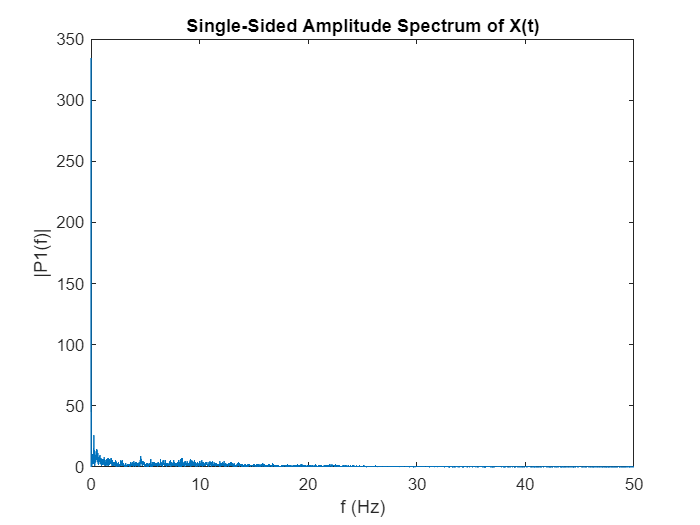

f = Fs*(0:(L2/2))/L2;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

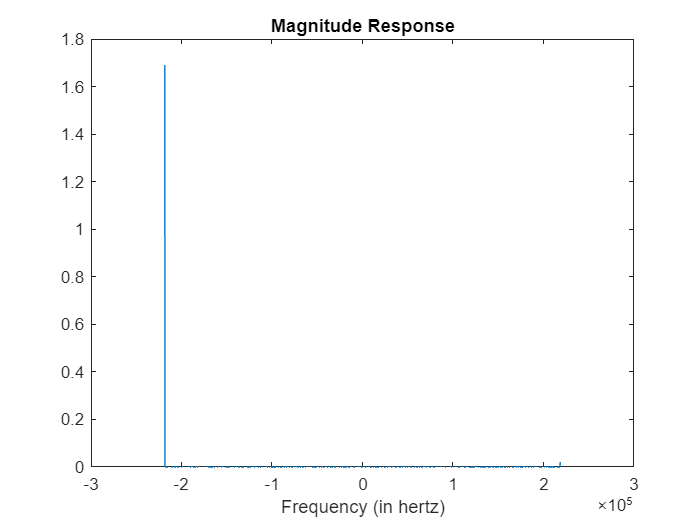

[Oscilo1, OscNfo]=readRigolWaveform('Oscilo/NewFile0.wfm');
dt = OscNfo.dx;             % Sampling period
Fs = 1/dt;            % Sampling frequency
StarTime=0;
N=size(Oscilo1,1);
StopTime = N*dt;                  % seconds
t = (StarTime:dt:StopTime-dt)';
Y = fft(Oscilo1);
P2 = abs(Y)./N;
%%Frequency specifications:
dF = Fs/N;                      % hertz
f = -Fs/2:dF:Fs/2-dF;           % hertz
%%Plot the spectrum:
figure;
plot(f,P2);
xlabel('Frequency (in hertz)');
title('Magnitude Response');